clc, clear all, close all

Paremeters

% Masses  [Kg]
M1 = 1;
M2 = 0.8;
m1 = 0.20;
m2 = 0.15;

% Lengths  [m]
L1 = 0.40;
L2 = 0.30;

% Stiffnesses  [N/m]
k1 = 50;
k2 = 30;

% Damping coefficients  [N*s/m]
c1 = 2.0;
c2 = 1;

% Torsional Stiffnesses  [N*m/rad]
kt1 = 0.30;
kt2 = 0.20;

% Gravitational Acceleration  [m/s^2]
g = 9.81;


Non Dimensional groups

eta1 = M1/m1;
eta2 = M2/m1;
eta3 = m2/m1;

lambda = L2/L1;

k = k2/k1;

csi1 = c1/sqrt(m1*k1);
csi2 = c2/sqrt(m1*k1);

kt_1 = kt1/(L1^2*k1);
kt_2 = kt2/(L1^2*k1);

g_bar = g*m1/L1/k1;

omega = sqrt(k1/m1);


Initial Conditions

% Initial Positions [m] and [rad]
x1_0 = 0.08;
x2_0 = -0.04;
theta1_0 = 0.5;
theta2_0 = -0.4;

% Initial Velocities [m/s] and [rad/s]
v1_0 = 0;
v2_0 = 0;
omega1_0 = 0;
omega2_0 = 0;


Dimensionless Initial Conditions

%% Initial Positions 
X1_0 = x1_0/L1;
X2_0 = x2_0/L1;
Theta1_0 = theta1_0;
Theta2_0 = theta2_0;

% Initial Velocities
V1_0 = v1_0/(L1*omega);
V2_0 = v2_0/(L1*omega);
Omega1_0 = omega1_0/omega;
Omega2_0 = omega2_0/omega;

Y0=[X1_0; X2_0; Theta1_0; Theta2_0; V1_0; V2_0; Omega1_0; Omega2_0];


Dimensionless time

tau_span = [0 20*omega];

params=struct('eta1',eta1,'eta2',eta2,'eta3',eta3,'lambda',lambda,'k',k,'csi1',csi1,'csi2',csi2,'kt_1',kt_1,'kt_2',kt_2,'g_bar',g_bar);


Solution of Differential Equations using ODE45

[tau , Y]=ode45(@(tau,Y) DimensionlessSystem(tau,Y,params),tau_span,Y0);

X1 = Y(:,1);
X2 = Y(:,2);
Theta1 = Y(:,3);
Theta2 = Y(:,4);
V1 = Y(:,5);
V2 = Y(:,6);
Omega1 = Y(:,7);
Omega2 = Y(:,8);


Results

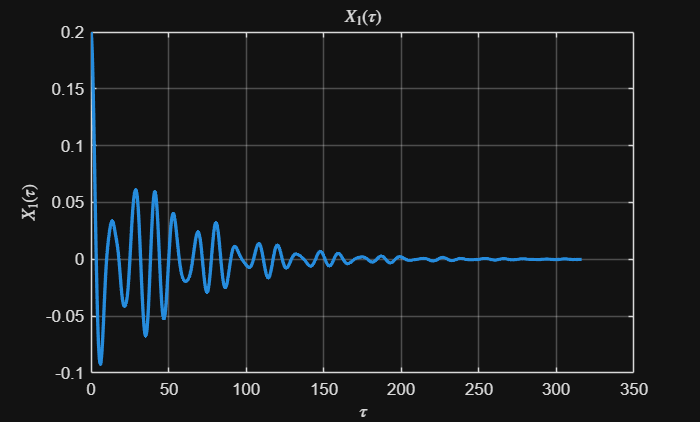

set(groot, 'DefaultLineLineWidth', 2);

figure;
plot(tau,X1),title('$X_1(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'), ylabel('$X_1(\tau)$',Interpreter='latex'), grid

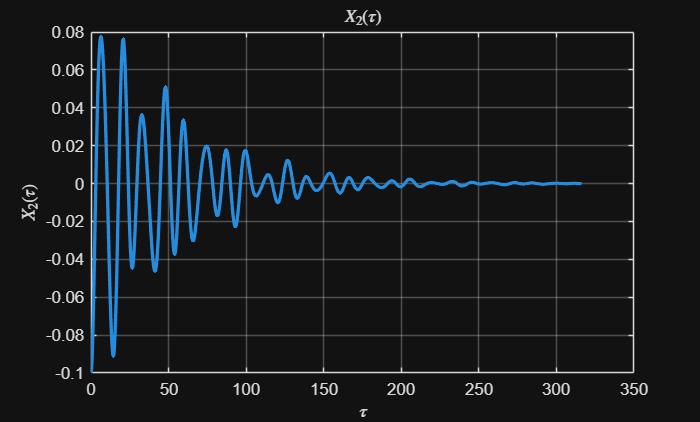


figure;
plot(tau,X2),title('$X_2(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$X_2(\tau)$',Interpreter='latex'),grid

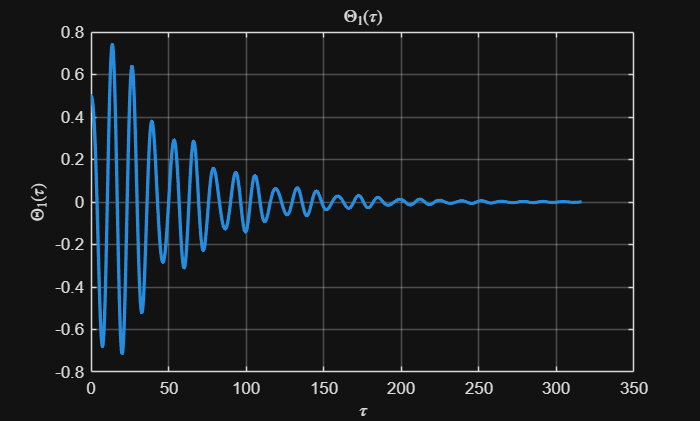


figure;
plot(tau,Theta1),title('$\Theta_1(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$\Theta_1(\tau)$',Interpreter='latex'),grid

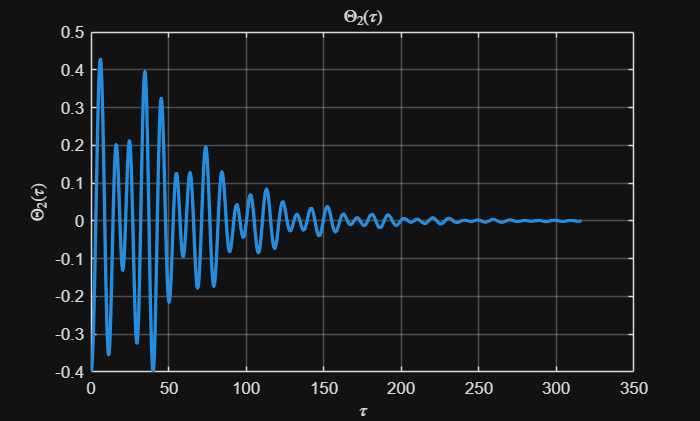


figure;
plot(tau,Theta2),title('$\Theta_2(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$\Theta_2(\tau)$',Interpreter='latex'),grid

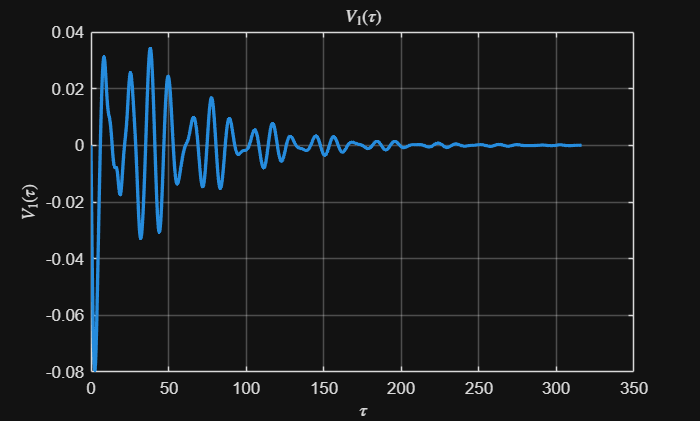


figure;
plot(tau,V1),title('$V_1(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$V_1(\tau)$',Interpreter='latex'),grid

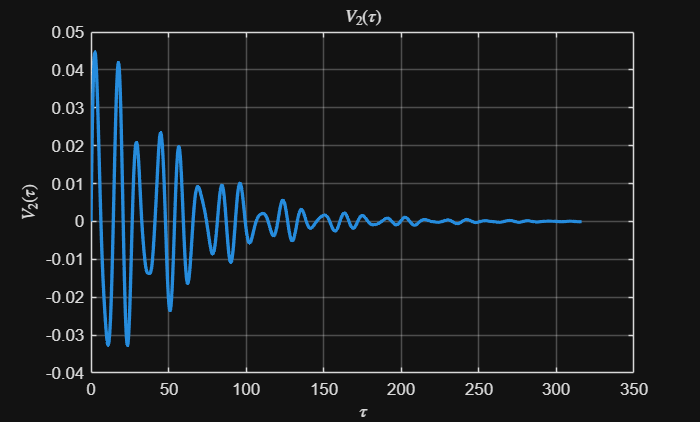


figure;
plot(tau,V2),title('$V_2(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$V_2(\tau)$',Interpreter='latex'),grid

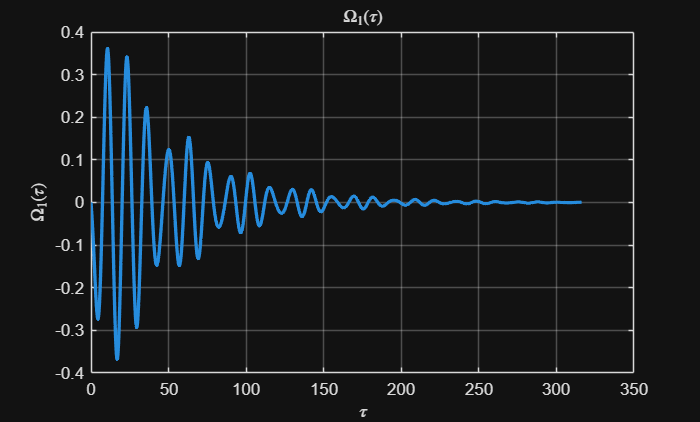


figure;
plot(tau,Omega1),title('$\Omega_1(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$\Omega_1(\tau)$',Interpreter='latex'),grid

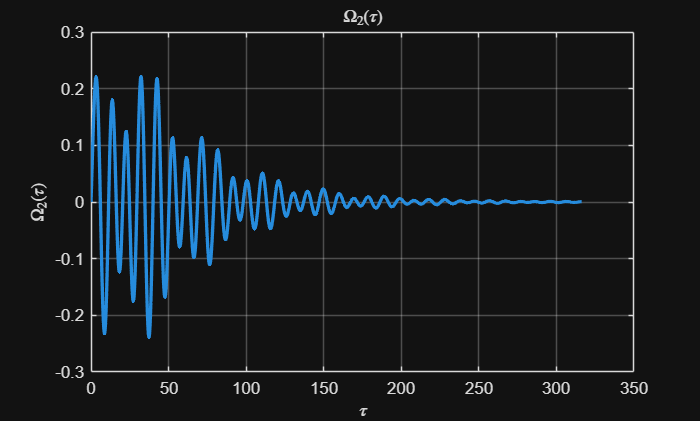


figure;
plot(tau,Omega2),title('$\Omega_2(\tau)$',Interpreter='latex'),xlabel('$\tau$',Interpreter='latex'),ylabel('$\Omega_2(\tau)$',Interpreter='latex'),grid

Differential Equations: Function

function dYdtau = DimensionlessSystem(~, Y, p)

% State variables
X1 = Y(1);  X2 = Y(2);  Th1 = Y(3);  Th2 = Y(4);
V1 = Y(5);  V2 = Y(6);  W1  = Y(7);  W2  = Y(8);

% Coefficients of DE
S1 = sin(Th1);  C1 = cos(Th1);
S2 = sin(Th2);  C2 = cos(Th2);

D1 = p.eta1 + 1 - 0.75*C1^2;
D2 = p.eta2 + p.eta3 - 0.75*p.eta3*C2^2;

Q1 = p.g_bar/2*S1 + p.kt_1*Th1;
Q2 = p.eta3*p.lambda*p.g_bar/2*S2 + p.kt_2*Th2;

P1 = 0.5*S1*W1^2 - X1 - p.csi1*V1 - p.k*(X1 - X2) - p.csi2*(V1 - V2);
P2 = p.eta3*p.lambda/2*S2*W2^2 - p.k*(X2 - X1) - p.csi2*(V2 - V1);

% Derivatives of State Variables
dV1 = (P1 + 1.5*C1*Q1) / D1;
dV2 = (P2 + 3*C2/(2*p.lambda)*Q2) / D2;
dW1 = (-3*(p.eta1 + 1)*Q1 - 1.5*C1*P1) / D1;
dW2 = (-3*(p.eta2 + p.eta3)*Q2/(p.eta3*p.lambda^2) - 3*C2/(2*p.lambda)*P2) / D2;

dYdtau = [V1; V2; W1; W2; dV1; dV2; dW1; dW2];
end